# Using a ResNet for Brain Tumor Classification

## 1. Overview of the Problem: Detecting Tumors Using Neural Networks

**This application of neural networks for tumor detection was adapted from** [Ismael, S. A. A., Mohammed, A., & Hefny, H. (2020).](http://Ismael, S. A. A., Mohammed, A., & Hefny, H. (2020).https://pubmed.ncbi.nlm.nih.gov/31980109/) An enhanced deep learning approach for brain cancer MRI images classification using residual networks. *Artificial intelligence in medicine*, *102*, 101779.

### Summary

**Computer-Assisted Diagnosis** is a deep learning technology aimed to help doctors and radiologists diagnose and classify tumors using imaging data. While humans are really good at doing this task manually, the process is labor intensive. Approaches to facilitate and automate diagnosis would be decrease healthcare costs and time consumed for manual diagnosis.

This paper used **transfer learning** to train a **Residual Network (ResNet)** to classify three kinds of cancers from MRI images. We will go over the essential parts of transfer learning and a high level overview of what a ResNet does. 

## 2. Preliminary theory

### A. Convolutional Neural Networks

### 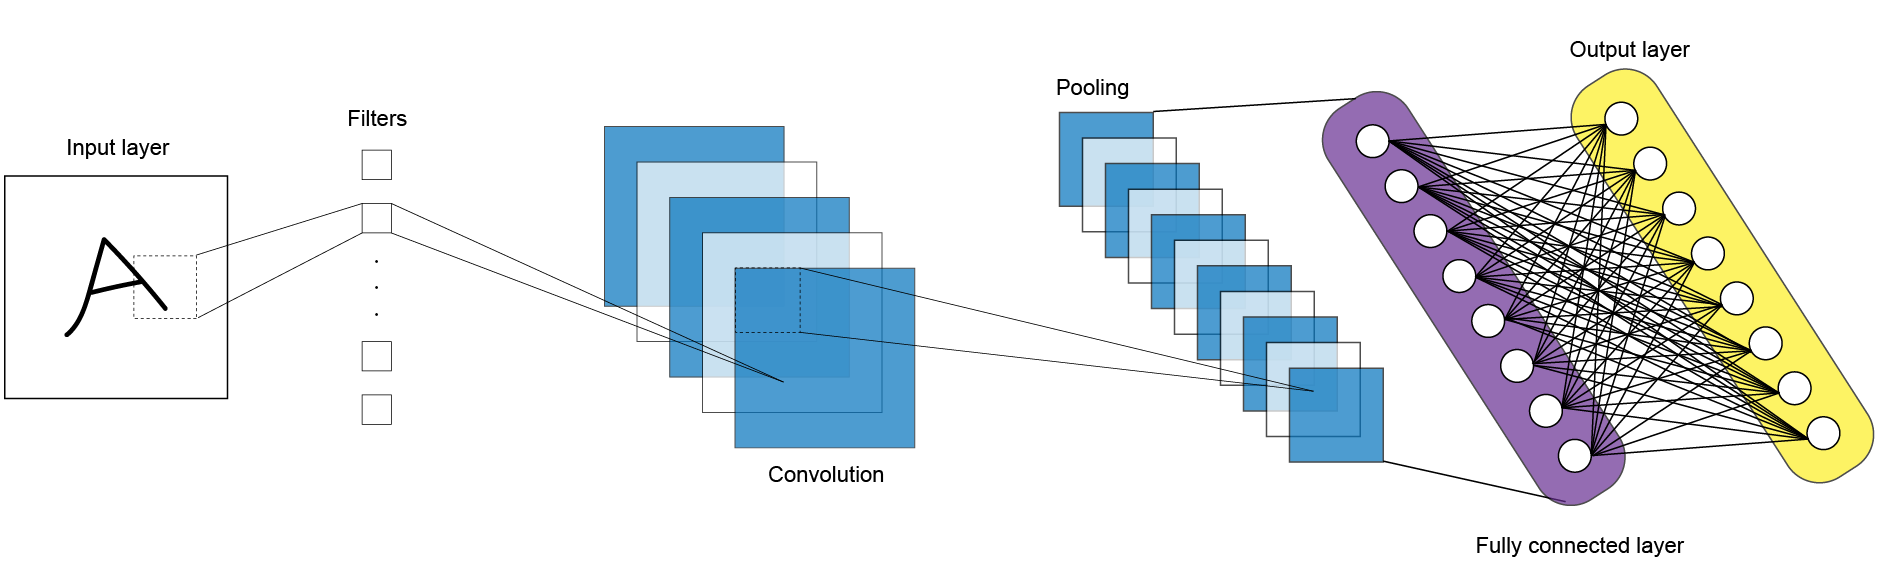

A **Convolutional Neural Network** consists of several additional layers that perform additional computations that are required to capture spatial information from an image. They work by scanning an image, learning attributes about an image (edges, contours, etc), and given new images can perform various regression and classification based tasks. This is broadly known as **computer vision** - enabling machines to "see" images and make decisions. Some tasks are described below.

#### Image classification

**Image classification** assigns a label with a given image.

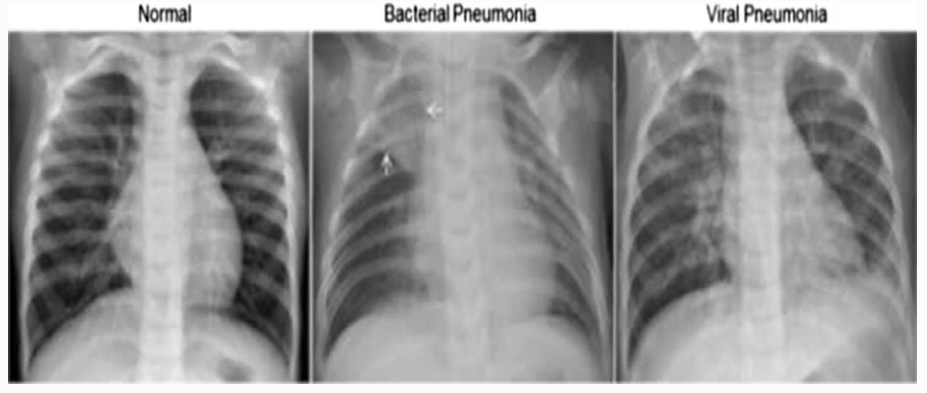

Image taken from Yadav, S. S., & Jadhav, S. M. (2019). Deep convolutional neural network based medical image classification for disease diagnosis. *Journal of Big Data*, *6*(1), 1-18.

#### Object detection

**Object detection** identifies a **boundary box** that locates and separate specific objects within an image. Shown below are boundary boxes that identify the fovea and the optical disk.

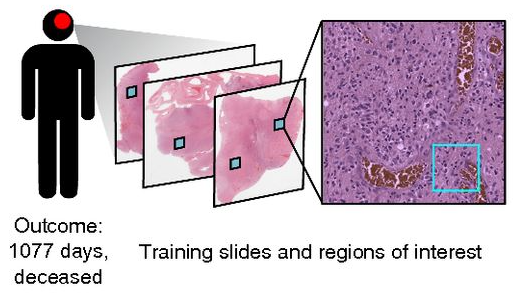

Image taken from Mobadersany et al., (2018). Predicting cancer outcomes from histology and genomics using convolutional networks. *Proceedings of the National Academy of Sciences*, *115*(13), E2970-E2979.

#### Object segmentation

**Object segmentation** identifies **sets of pixels** that are able to locate objects and boundaries for specific objects within an image. Shown below is a segmentation border that shows the optical disk in the eyeball.

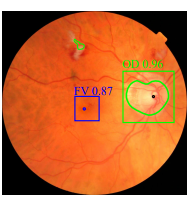

Image taken from Araújo, et al (2018). UOLO-automatic object detection and segmentation in biomedical images. In *Deep Learning in Medical Image Analysis and Multimodal Learning for Clinical Decision Support* (pp. 165-173). Springer, Cham.

#### Neural style transfer

**Neural style transfer** uses deep learning to compose an image in the style of another image! More information can be found [here](https://www.tensorflow.org/tutorials/generative/style_transfer).

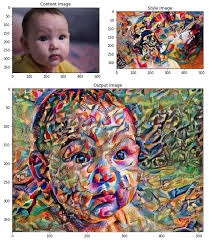

Image taken [Flickr](https://www.flickr.com/photos/arielst0rm7/49245378138) 

#### **Summary**

Convolutional neural networks are a highly flexible and accurate algorithm for image-based tasks. Below is a one-sentence description of each layer we need to train, and that we'll describe in more detail later:

- **Convolution layer**: an information extraction layer.

- **Pooling layer**: a dimension reduction layer.

- **Activation layer**: a non-linear function.

- **Fully connected layer**: a feedforward neural network.

#### Convolution Layer

An image can be represented as a **tensor**: a multi-dimensional matrix in terms of height, width, and the number of colors. 

For simplicity, we'll only consider gray-scale images, where there is only 1 color dimension. Thus, the image size is two-dimensional, with a height and width.

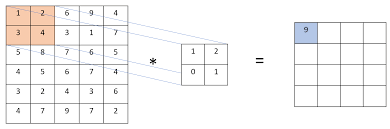

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Convolution.PNG)

In the convolution layer, we're scanning an image (*left*) using a **filter** - a smaller matrix (*middle*) that can capture intrinsic features of the image (think edges, shades, etc). **The objective of the neural network is to learn the best set filters that can be generalized across different images to capture intrinsic data structures.** 

While the image is scanned, the area that is being scanned by the filter is beeing combined through **matrix multiplication**. The resulting matrix is called the** feature map** - a condensed representation of the image (*right*). 

All together, this entire computational process is called a **convolution**.

#### Pooling Layer

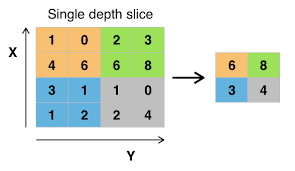

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Max_pooling.png).

Once we obtain a feature map, the data is condensed even further in the **pooling layer. **The purpose of the pooling layer is to **reduce the computational costs** downstream and **perform feature extraction** for the most important features in an image.   

#### Activation Layer: Rectified Linear Units (ReLUs)

We have seem what the sigmoid activation function does - it transforms data into the range of [0, 1], corresponding to probabilities. Now we will consider a new function: the **Rectified Linear Unit (ReLU)**.

The ReLU floors values to be 0 if the value is negative, or to be that value if positive. A plot of the ReLU distribution is shown below.

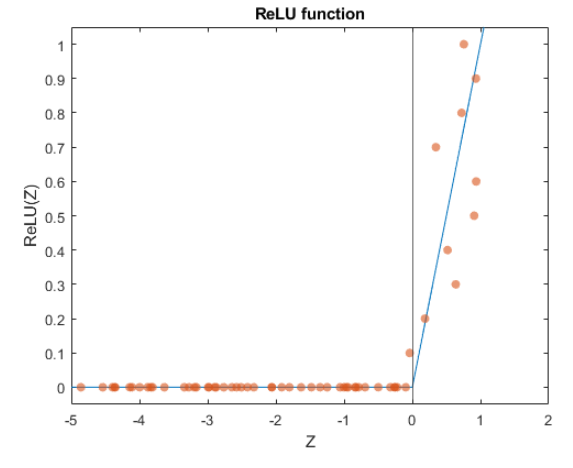

**There are several reasons why the ReLU performs well in convolutional neural networks**:

- The gradient during backpropagation is not saturated with a ReLU.

- The ReLU introduces sparsity and is a simple operation to perform, decreasing computational overhead.

#### Fully Connected Layer

From here, we perform a feedforward neural network computation. A schematic of the computation is shown below for review.

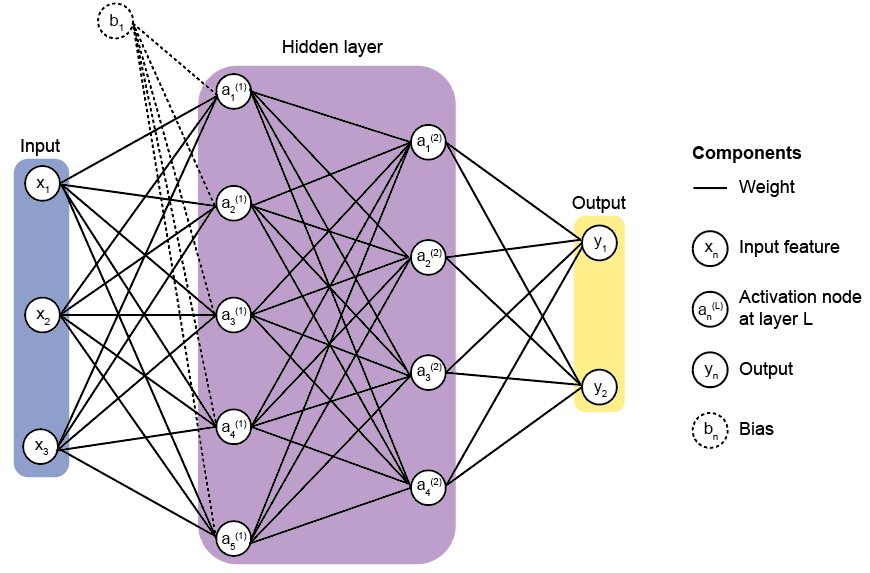

#### Loss Layer 

Finally, we can evaluate the loss. We'll be using the cross entropy loss function, with the goal to minimze the loss.

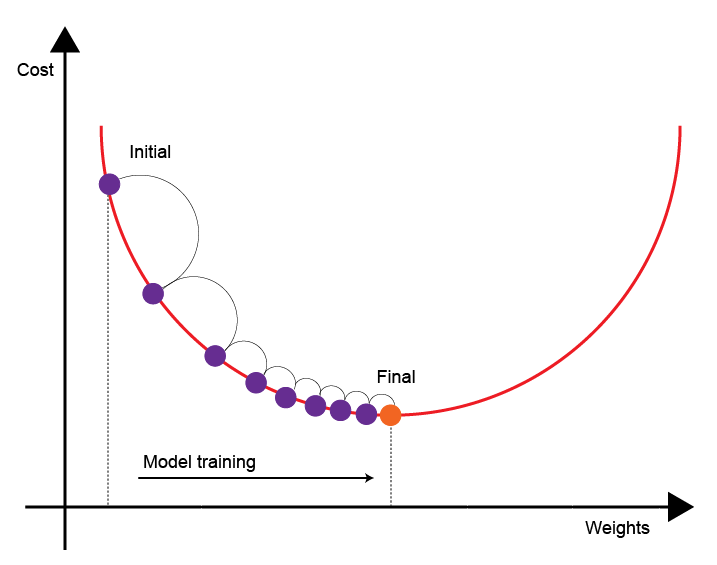

### B. Transfer learning

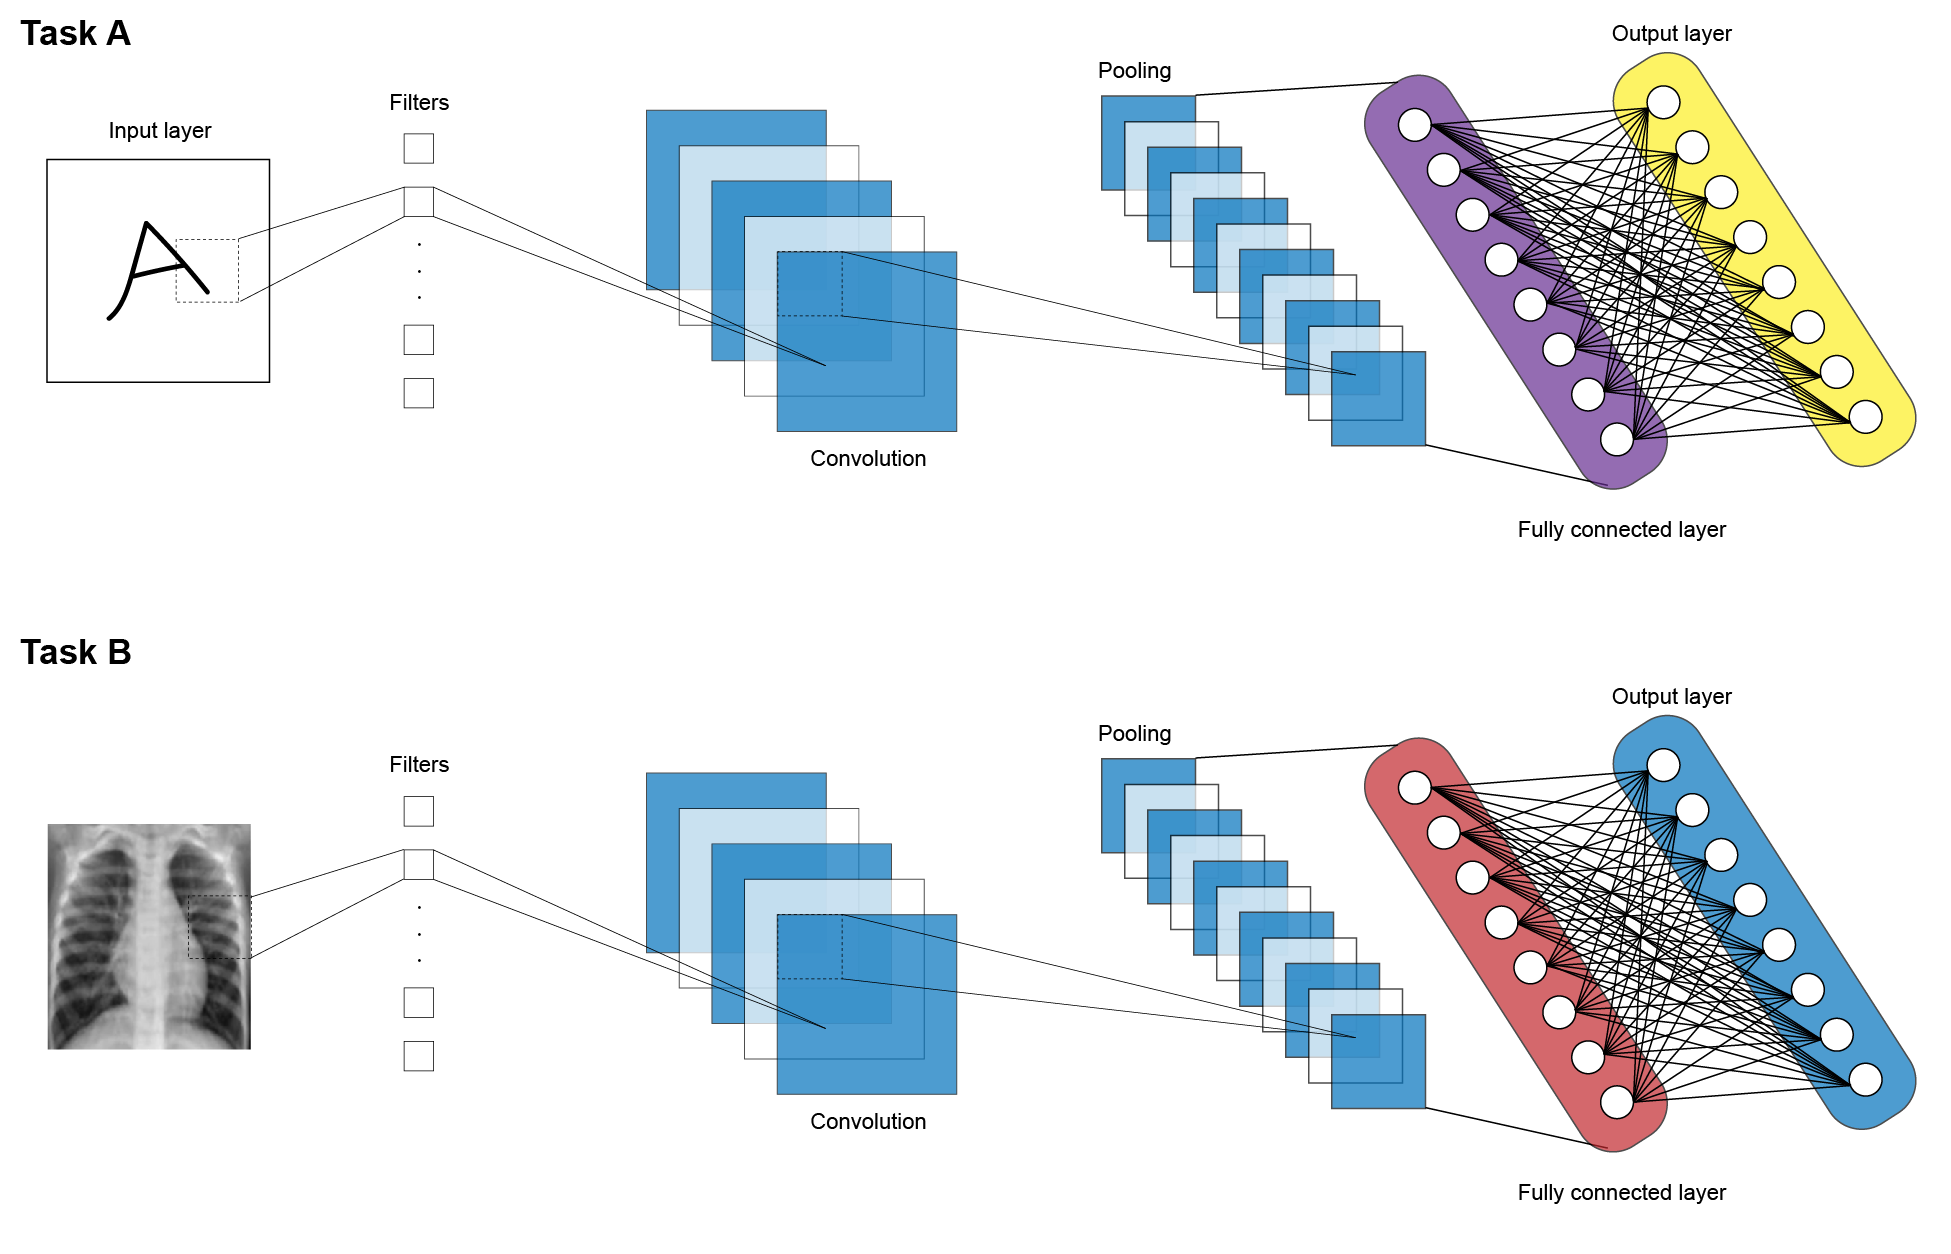

Convolutional neural networks learn filters that can extract specific attributes within an image, and are known as really great **feature extractors. **Because attributes such as edges are universal, this allows us to take these filters and apply them for other tasks. 

This is known as **transfer learning: **using pretrained weights that were initially trained on one task for another prediction, assuming that the filters used are universal. We can take the filters trained from previously models and apply them to new tasks. While the core convolutional layers are important, the outer layers are responsible for identifying task-specific features. **These outer layers need to be re-trained to be task-specific.**

**The pros of transfer learning:**

- Save a lot of time (and money) on training a model.

- Reduce data requirements.

- Neural networks tend to work with high degree of accuracy, despite our shortcut.

**When transfer learning is not possible:**

- If the data distribution is totally different (like text to images), then the model will still suck

- The goal is to achieving human-level accuracy (usually around 97-99%)

- You need statistically robust measures to assess and detect sources of model error

We will use transfer learning to train an image classifier, using filters from residual networks as the base model.

### C. Residual Networks

A general trend with deep neural networks is that the deeper you go, the more accurate the model gets. However, the main issue with deep neural networks is not overfitting, but the **vanishing gradient problem:** we lose information about errors as we go deeper into the network because of the backpropagation computations.

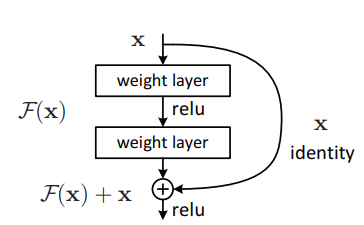

Image taken from [He et al., 2015](http://He et al., 2015https://arxiv.org/abs/1512.03385).

To solve the vanishing gradient problem, [He et al., 2015](http://He et al., 2015https://arxiv.org/abs/1512.03385) introduced **Residual Networks (ResNets)**. The idea is to introduce shortcut connections by skipping one or more layers in the deep neural network. **This allows an alternate path for the gradient we compute in backpropagation to go through, increasing information obtained**. This ensures that the deeper layers will perform at least as well as shallower layers. 

Since the original 2015 publication, there are several flavors of ResNets. **In our image classification task, we'll use ResNet50, a neural network that is 50 layers deep.**

### D. Data Augmentation

Neural networks need a lot of data to prevent overfitting and to adequately learn the features associated with a given task. However, image annotation and manual segmentation can be very time-consuming and expensive to generate. To increase the utility of a smaller existing dataset, you can apply random but realistic transformations to the existing dataset. This is known as **data augmentation**. 

Some common augmentations are shown in the figure below.

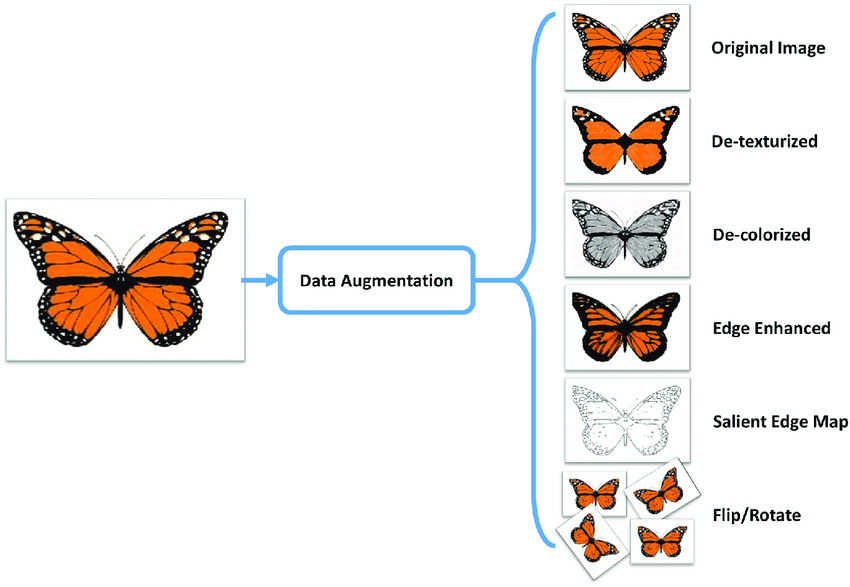

Image taken from[ Sourav Kumar Medium article](https://medium.com/secure-and-private-ai-writing-challenge/data-augmentation-increases-accuracy-of-your-model-but-how-aa1913468722).

In ourr image classification task, **we'll apply rotation, reflection, and shearing. **

## 3. Load data

First, we'll load the MRI dataset from [Swati et al (2019)](https://pubmed.ncbi.nlm.nih.gov/31150950/). Brain tumor classification for MR images using transfer learning and fine-tuning. *Computerized Medical Imaging and Graphics*, *75*, 34-46. 

### A. Description of the dataset

The data has already been preprocessed in the provided data directory. Each subdirectory corresponds to an image of a given cancer (glioma, meningioma, or pituitary cancer). Each .mat file contains 2D (gray scale) integer matrix of the image data. 

To download the dataset, go to this [link](https://figshare.com/articles/dataset/brain_tumor_dataset/1512427) and download the entire dataset (~1GB). They split the images into three folders. Put all the .mat files into a single folder called dataset. 

% Clear workspace
clear all
 
% Images Datapath – Please modify your path accordingly 
datapath='D:/Data/Brain_img/final_dataset';

### B. Load and preprocess data

Now we need to create a `datastore` object - a container MATLAB uses to read-in files. This can be achieved using the [`imageDatastore()`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html?searchHighlight=imagedatastore&s_tid=srchtitle) function. 

**An important note:** a custom read function `matRead() `is called with the `ReadFcn` argument. This function file is in the provided directory. This function un-nests the integer matrix from a structure and performs min-max scaling for each image, which scales the pixels (ranging from 0 to 255) to have a value between 0 and 1. The formula and docstring for the `MinMaxScale()` function is show below.


$$X_{\mathrm{minmax}} =\frac{X_{\mathrm{ij}} -\mathrm{min}\left(X_j \right)}{\mathrm{max}\left(X_j \right)-\mathrm{min}\left(X_j \right)}$$


% Image Datastore
imds = imageDatastore(fullfile(datapath), ...
                   'ReadFcn', @matRead, ...
                   'IncludeSubfolders', true, ...
                   'LabelSource', 'foldernames', ...
                   'FileExtensions','.mat');

## 4. Visualize image

Let's read in a single file using the [`readimage()`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.readimage.html) function and visualize it using the [`imshow()`](https://www.mathworks.com/help/images/ref/imshow.html?searchHighlight=imshow&s_tid=srchtitle) function.

img = readimage(imds, 1);

Note that if we visualize the image as is, the contrast is not that great. Our algorithm will also find it hard to distinguish edges as well.

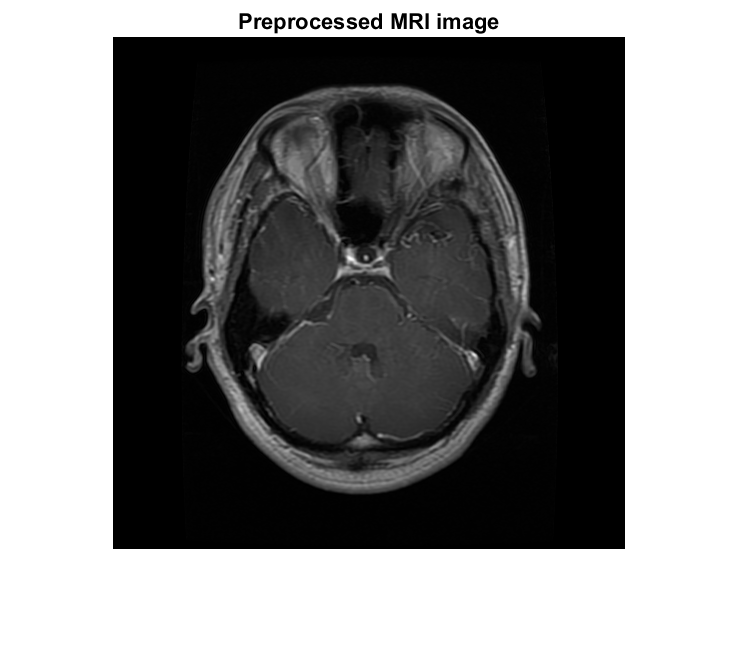

imshow(img);
title("Preprocessed MRI image")

## 5. Training a ResNet using transfer learning

Now we'll implement transfer learning using the [ResNet50](https://www.mathworks.com/help/deeplearning/ref/resnet50.html) model for a simple classification task. 

### A. Balance dataset

First, let's count the number datapoints corresponding to each cateogory in the dataset.

tbl = countEachLabel(imds)

tbl = 3×2 table
      Label       Count
    __________    _____

    glioma        1426 
    meningioma     708 
    pituitary      930 


Note that we have an unequal number of images per catgory. Let's create a balanced dataset. Note that in practice, you would want to do the full 708 images. To save time, we'll run this code on 100 images. 

% Determine the smallest amount of images in a category
%minSetCount = min(tbl{:,2}); % FOR ALL 708 IMAGES
minSetCount = 100; 

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 3×2 table
      Label       Count
    __________    _____

    glioma         100 
    meningioma     100 
    pituitary      100 


### B. Loading the ResNet50 model

Now let's load the model. 

**IMPORTANT NOTE:** You do have to download and install an additional MATLAB tooblox called [Deep Learning Toolbox Model for ResNet-50 Network](https://www.mathworks.com/help/deeplearning/ref/resnet50.html)**.**

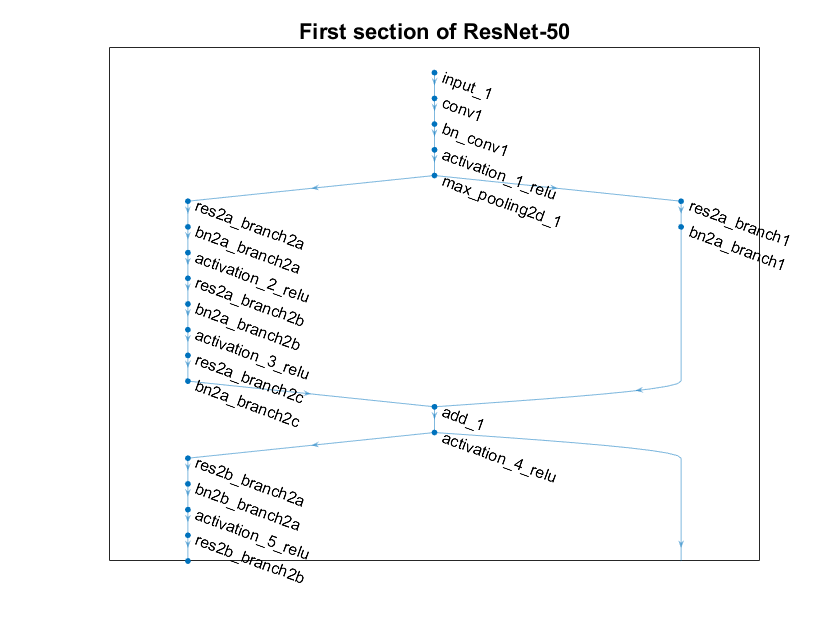

% Load ResNet
net = resnet50();

% Visualize a few layers
figure;
plot(net)
title("First section of ResNet-50");
set(gca,'YLim',[150 170]);

Now let's create a copy of the network that we'll use for fine tuning.

CANCER_MDL = layerGraph(net);

### C. Create new layers for transfer learning.

We'll replace the fully connected layer at the head of the model - this contains all the fine-tuning weights that are specific for a given task. The layers we have to replace include:

- The fully connected layer

- The softmax layer

- The classification layer

% Fully connected layer
NUM_CLASSES     = 3;
MRI_FC_LAYER    = fullyConnectedLayer(NUM_CLASSES, ...
                                      'Name', 'MRI_FC', ...
                                      'WeightLearnRateFactor', 10, ...
                                      'BiasLearnRateFactor',10);
CANCER_MDL      = replaceLayer(CANCER_MDL, 'fc1000', MRI_FC_LAYER);

% Softmax layer
MRI_SOFTMAX     = softmaxLayer('Name','MRI_Softmax');
CANCER_MDL      = replaceLayer(CANCER_MDL, 'fc1000_softmax', MRI_SOFTMAX);

% Classification layer
MRI_CLASSIFY    = classificationLayer('Name', 'CANCER_CLASSIFIER');
CANCER_MDL      = replaceLayer(CANCER_MDL, 'ClassificationLayer_fc1000', MRI_CLASSIFY);

### D. Create the training and test set

Now we can create a traning and test set using the [`splitEachLabel()`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html?searchHighlight=splitEachLabel&s_tid=srchtitle) function. We'll do an 80/20 split.

[trainingSet, testSet] = splitEachLabel(imds, 0.2, 'randomize');

### E. Preprocess data images

To perform some data preprocessing, we'll perform the following steps:

- Resize the data to fit ResNet-50 specifications

- Add some augmentations to make the model more robust

- Apply to the dataset

Note that ResNet50 was trained on colored, resulting in a 3D tensor of the dimensions (height, width, color). What the` 'ColorPreprocessing'` argument does is it fills the color dimension with the same values for all colors with the `gray2rbg` value.

% Data Augumentation method
augmenter = imageDataAugmenter(...
                               'RandRotation', [-5 5], ...
                               'RandXReflection', 1, ...
                               'RandYReflection', 1, ...
                               'RandXShear', [-0.05 0.05], ...
                               'RandYShear', [-0.05 0.05]);

% Get ResNet input size to re-scale images using the augmentor
IMG_DIM = net.Layers(1).InputSize;

% Apply augmentation to the training data only using the augmenter method we specified.
augTrainData  = augmentedImageDatastore(IMG_DIM, ...
                                        trainingSet, ...
                                        'DataAugmentation', augmenter, ...
                                        'ColorPreprocessing', 'gray2rgb');
augTestData   = augmentedImageDatastore(IMG_DIM, ...
                                        testSet, ... 
                                        'ColorPreprocessing', 'gray2rgb');

### F. Specify model hyperparameters

Now let's specify some model hyperparameters using the [`trainingOptions()`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html?searchHighlight=trainingoptions&s_tid=srchtitle) function. 

% Training Options, we choose a small mini-batch size due to limited images 
options = trainingOptions(...
                          'adam',...                     % ADAM Optimization
                          'MaxEpochs', 5, ...            % Number of epochs without early stopping
                          'MiniBatchSize', 8,...         % Mini-batches (don't worry about it)
                          'Shuffle','every-epoch', ...   % Shuffling data 
                          'InitialLearnRate', 1e-4, ...  % Initial learning rate - related to ADAM
                          'Verbose', true, ...           % Show warnings if any
                          'Plots','training-progress');  % Show model progress

### G. Model training

Now that we've set up the model and the data, let's train the new model.

% Training
[MRI_ResNet, trainingInfo] = trainNetwork(augTrainData, CANCER_MDL, options);

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:04 |        0.00% |       1.3581 |      1.0000e-04 |


|       5 |          35 |       00:00:38 |      100.00% |       0.0429 |      1.0000e-04 |
|========================================================================================|


Once the model has been trained, we'll classify the labels.

[predicted_labels, posterior] = classify(MRI_ResNet, augTestData);

### H. Validation

Let's visualize the results using a confusion matrix.

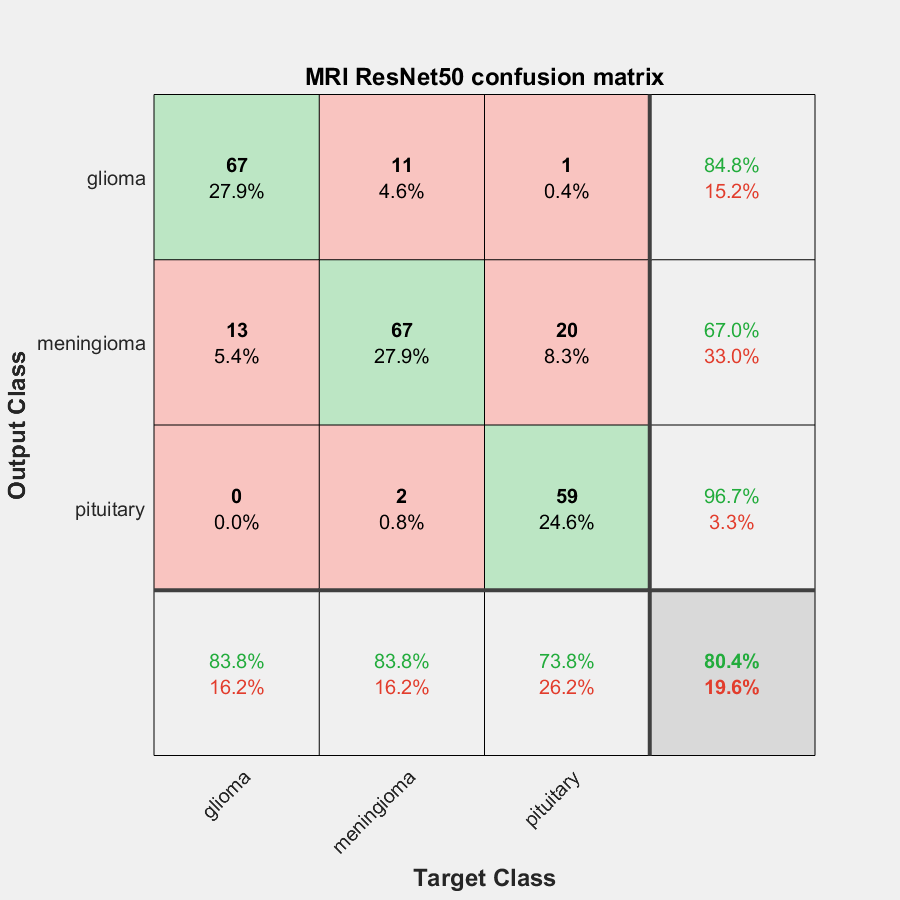

figure;
plotconfusion(testSet.Labels, predicted_labels)
title('MRI ResNet50 confusion matrix');

## 6. Summary

We used transfer learning to fine tune a deep convolutional neural network to recognize and classify MRI images for cancer with 80% accuracy. Considering we haven't done any fine tuning, that's actually pretty good! 

Convolutional neural networks can be used to solve a wide-variety of tasks, and their implementation in the biomedical space is coming. Have at it!